# AAE340 HW#6

## PROBLEM #6 (MATLAB)

## <6c>

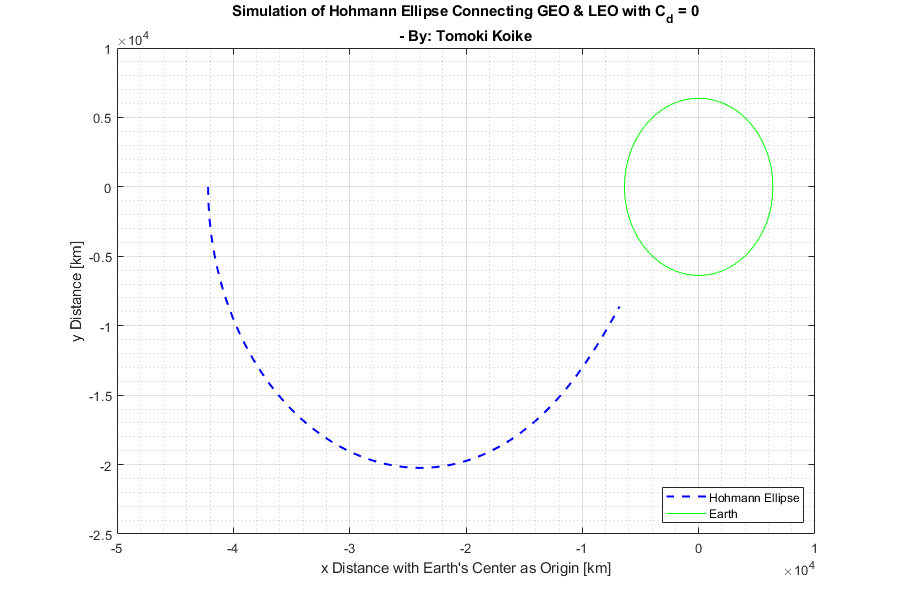

clear all
close all
clc

% Assigning variables to the constants
R_earth         = 6376;                 % Earth's radius [km]
r_ref           = 6458;                 % Reference dsitance [km]
rho_ref         = 7.7*10^3;             % Reference density [kg/km^-3]
H               = 5;                    % Scale height [km]
m               = 1000;                 % Mass [kg]
S               = 1*10^(-6);            % Cross-sectional area [m^2]
mu              = 3.986*10^5;           % Gravitational constant [km^3/s^2]
Cd              = 0;                    % Drag coefficient

% Initial conditions
r0              = 42166;                % r(0) [km]
theta0          = pi;                   % theta(0) [rad]
v0              = 1.59709;              % v(0) [km/s]
gamma0          = 0;                    % gamma(0) [rad]
r_dot0          = v0*sin(gamma0);       % r_dot(0) [km/s]
v_dot0          = -mu*sin(gamma0)/r0^2 - rho_ref*exp((r_ref-r0)/H)*S*Cd*v0^2/2/m;
                                        % v_dot(0) [km/s^2]
theta_dot0      = v0*cos(gamma0)/r0;    % theta_dot(0) [rad/s]
gamma_dot0      = v0*cos(gamma0)/r0 - mu*cos(gamma0)/r0^2/v0; 
                                        % gamma_dot(0) [rad/s]
i_cond          = [r0, r_dot0, v0, v_dot0, theta0, theta_dot0, gamma0, gamma_dot0];
                                        % All initial conditions

%Solving with ode45
t_span          = 1:86400;              % Time interval
[t1, x1]        = ode45(@(t,x) dfeq(t,x,Cd), t_span, i_cond);
r1              = x1(:,1);              % r-values
theta1          = x1(:,5);              % theta-values

% Earth
x_earth         = R_earth.*cos(0:0.0001:2*pi);      
                                        % x-values for earth circumference
y_earth         = R_earth.*sin(0:0.0001:2*pi); 
                                        % y-values for earth circumference
                                        
% Hohmann ellipse
x_traj          = r1.*cos(theta1);       % x-values of the simulated trajectory
y_traj          = r1.*sin(theta1);       % y-values of the simluated trajectory

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(x_traj, y_traj, '--b', 'LineWidth', 1.5)
xlabel('x Distance with Earth''s Center as Origin [km]')
ylabel('y Distance [km]')
title({['Simulation of Hohmann Ellipse Connecting GEO & LEO ' ...
    'with C_d = 0'], '- By: Tomoki Koike'})
hold on
plot(x_earth, y_earth, '-g')
hold off
grid on
grid minor
box on
legend('Hohmann Ellipse', 'Earth', 'Location', 'southeast')

## <6d>

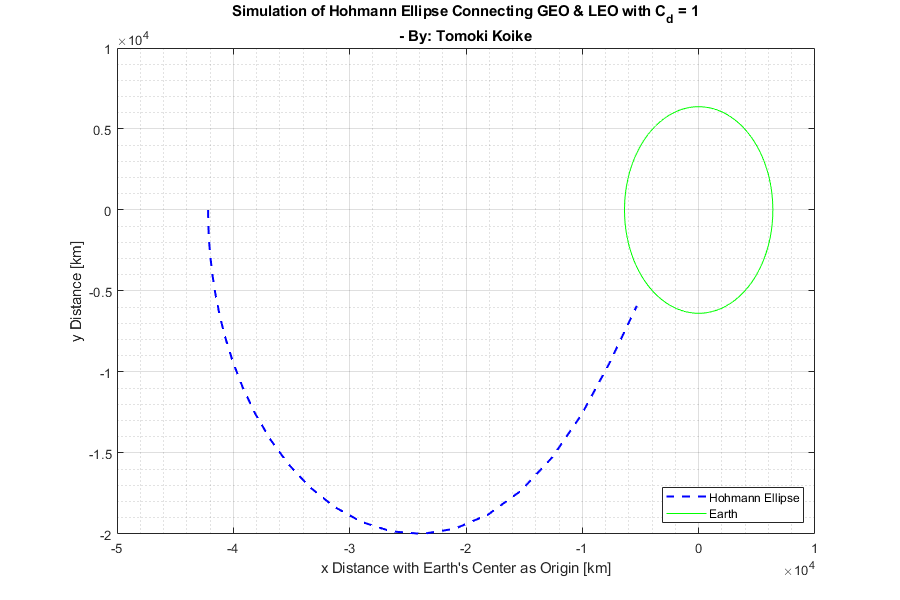

% Change Cd
Cd              = 1;                    % Drag coefficient

% Initial conditions
r0              = 42166;                % r(0) [km]
theta0          = pi;                   % theta(0) [rad]
v0              = 1.58335;              % v(0) [km/s]
gamma0          = 0;                    % gamma(0) [rad]
r_dot0          = v0*sin(gamma0);       % r_dot(0) [km/s]
v_dot0          = -mu*sin(gamma0)/r0^2 - rho_ref*exp((r_ref-r0)/H)*S*Cd*v0^2/2/m;
                                        % v_dot(0) [km/s^2]
theta_dot0      = v0*cos(gamma0)/r0;    % theta_dot(0) [rad/s]
gamma_dot0      = v0*cos(gamma0)/r0 - mu*cos(gamma0)/r0^2/v0; 
                                        % gamma_dot(0) [rad/s]
i_cond          = [r0, r_dot0, v0, v_dot0, theta0, theta_dot0, gamma0, gamma_dot0];
                                        % All initial conditions

% Set error tolerance 
option = odeset('RelTol',1e-6);   

%Solving with ode45
t_span          = 1:10:86400;           % Time interval
[t2, x2]        = ode45(@(t,x) dfeq(t,x,Cd), t_span, i_cond, option);
r2              = x2(:,1);              % r-values
theta2          = x2(:,5);              % theta-values

% Hohmann ellipse
x_traj2          = r2.*cos(theta2);       % x-values of the simulated trajectory
y_traj2          = r2.*sin(theta2);       % y-values of the simluated trajectory

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(x_traj2, y_traj2, '--b', 'LineWidth', 1.5)
xlabel('x Distance with Earth''s Center as Origin [km]')
ylabel('y Distance [km]')
title({['Simulation of Hohmann Ellipse Connecting GEO & LEO ' ...
    'with C_d = 1'], '- By: Tomoki Koike'})
hold on
plot(x_earth, y_earth, '-g')
hold off
grid on
grid minor
box on
legend('Hohmann Ellipse', 'Earth', 'Location', 'southeast')

## Function

function dxdt = dfeq(t,x,Cd)
% Constants 
r_ref           = 6458;                 % Reference dsitance [km]
rho_ref         = 7.7*10^3;             % Reference density [kg/km^-3]
H               = 5;                    % Scale height [km]
m               = 1000;                 % Mass [kg]
S               = 1*10^(-6);            % Cross-sectional area [m^2]
mu              = 3.986*10^5;           % Gravitational constant [km^3/s^2]
R_earth         = 6376;                 % Earth's radius [km]

% Defining state variable forms
dxdt            = zeros(8,1);           % Defining a zero vector to store the dxdt terms 
dxdt(1)         = x(2);  
dxdt(2)         = x(3)*sin(x(7));  
dxdt(3)         = x(4);  
dxdt(4)         = -mu*sin(x(7))/(x(1))^2 - rho_ref*exp((r_ref-x(1))/H)*S*Cd*(x(3))^2/2/m; 
dxdt(5)         = x(6);
dxdt(6)         = x(3)*cos(x(7))/x(1);
dxdt(7)         = x(8);
dxdt(8)         = x(3)*cos(x(7))/x(1) - mu*cos(x(7))/(x(1))^2/x(3);
end  